# Predict Behaviour from Ca2+ signal using Machine learning

To see whether the information contained in the dendritic tree is able to predict the current behavioural state of the animal, we can try to use classification or regression between the Ca2+ signal and some behavioural metrics.

## Predictors

The approach requires some predictors, which, in our case are obtained from the GCaMP signal obtained from different part of the dendritic tree. We can use either the entire dendritic tree, or a subset of ROIs from the dendritic tree, or the average between different groups of ROIs (obtained, for example from a previous clustering analysis)

## Predictors preprocessing

Predictors correspond to Ca2+ signal. However, a number of preprocessing steps can be used:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use the obj.rescaled_traces variables (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Observations

If we want to predict the behaviour from the Ca2+, we can use obj.behaviours. Classifiers require a binnarization step, while regression do not

## Example

The out-of-sample misclassification rate is 43.6%


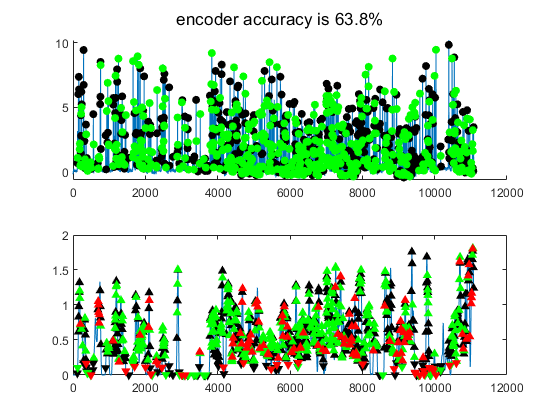

The out-of-sample misclassification rate is 11.2%


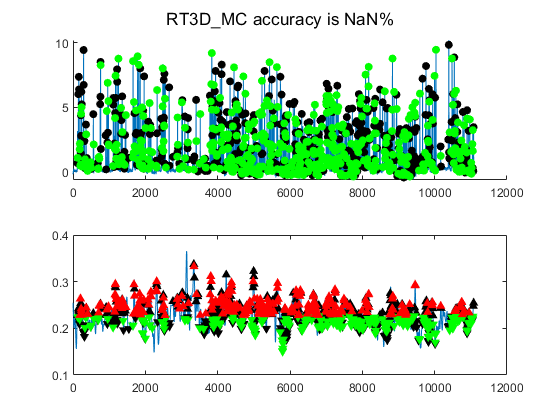

The out-of-sample misclassification rate is 18.4%


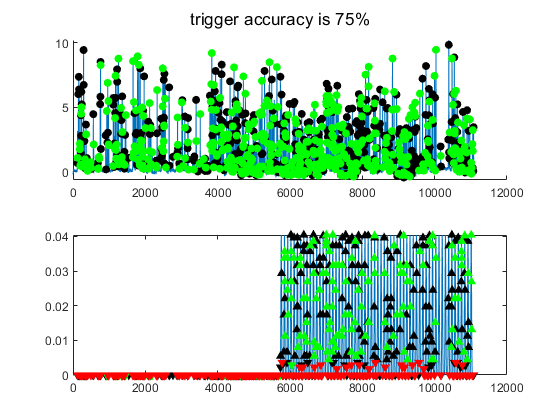

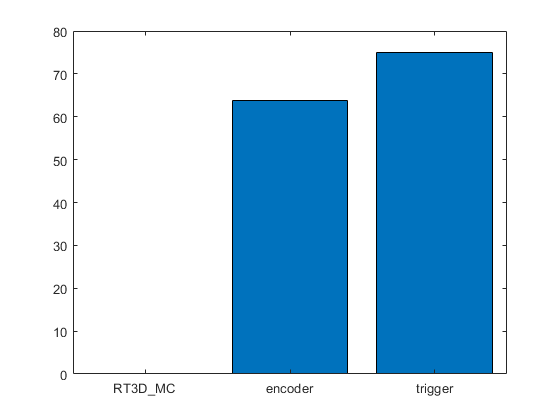

out = struct with fields:
        calcium: [11080×1 single]
        bin_beh: {[1×993 logical]  [1×993 logical]  [1×993 logical]}
        peak_tp: {[1×993 double]  [1×993 double]  [1×993 double]}
    train_range: {[1×496 double]  [1×496 double]  [1×496 double]}
     prediction: {[497×1 logical]  [497×1 logical]  [497×1 logical]}
       full_beh: {[1×11080 double]  [1×11080 double]  [1×11080 double]}
       beh_type: {'encoder'  'RT3D_MC'  'trigger'}
          score: {[63.7872]  [NaN]  [75]}


% This is the default case : svm classifier
out = predict_behaviours(obj, true, 'svm')

Note that the predictor and the observations are sent to the base workspace in case you wanted to try different methods using the Classfication Learner App from MATLAB.

## Running a classifier on the rescaled peaks

The out-of-sample misclassification rate is 47.2%


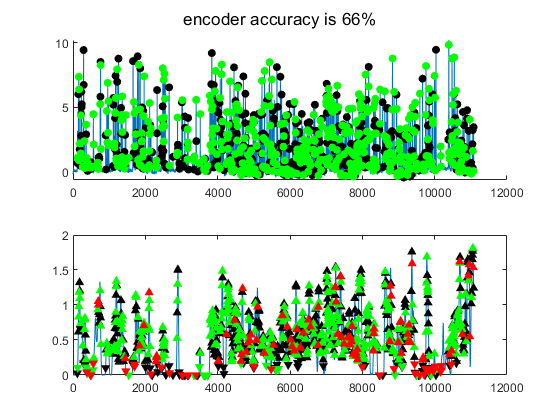

The out-of-sample misclassification rate is 10.7%


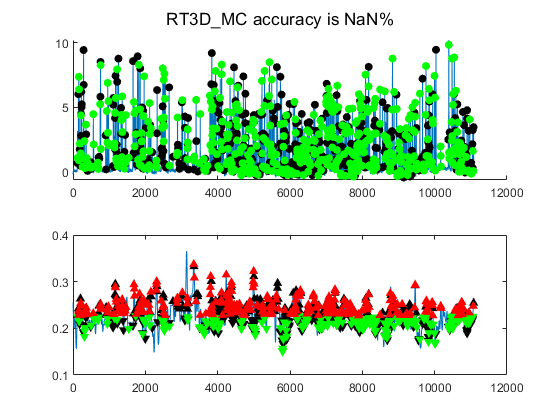

The out-of-sample misclassification rate is 23.3%


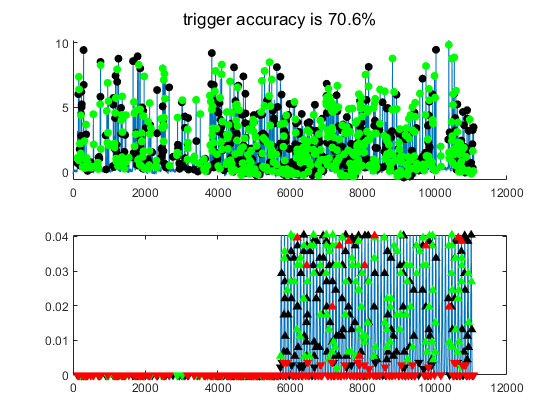

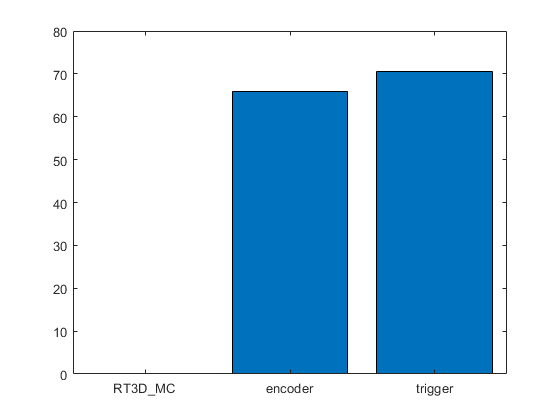

out = struct with fields:
        calcium: [11080×1 single]
        bin_beh: {[1×993 logical]  [1×993 logical]  [1×993 logical]}
        peak_tp: {[1×993 double]  [1×993 double]  [1×993 double]}
    train_range: {[1×496 double]  [1×496 double]  [1×496 double]}
     prediction: {[497×1 logical]  [497×1 logical]  [497×1 logical]}
       full_beh: {[1×11080 double]  [1×11080 double]  [1×11080 double]}
       beh_type: {'encoder'  'RT3D_MC'  'trigger'}
          score: {[65.9513]  [NaN]  [70.5882]}


% This will now take into account the magnitude of the response
out = predict_behaviours(obj, '', '', 'rescaled_peaks')